## Case Study: Self-Organizing Sequential Search Rules

### Warren D. Craft

#### Based on class discussion and examples

#### in CS 533: Experimental Methods in CS

#### (Spring 2019, University of New Mexico, taught by A. Mueen and G. M. Fricke)

First, some slides from the related lecture (Spring 2019), …

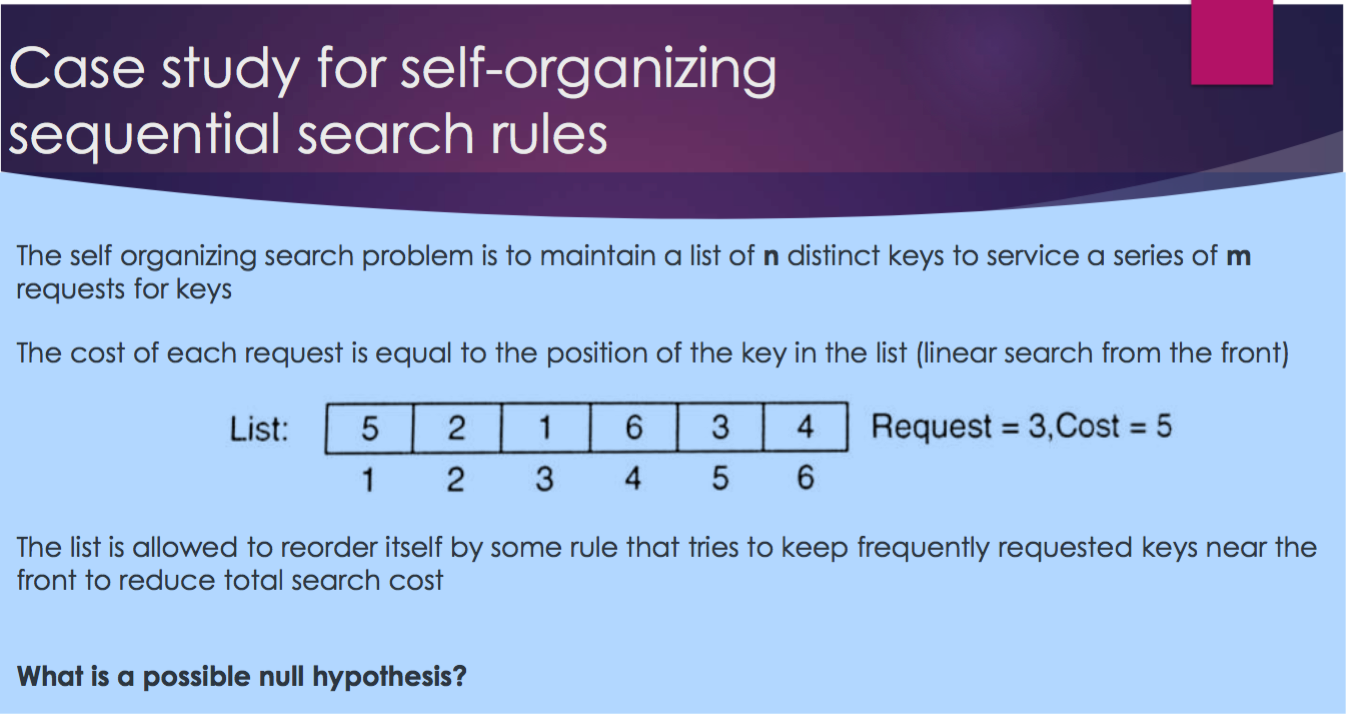  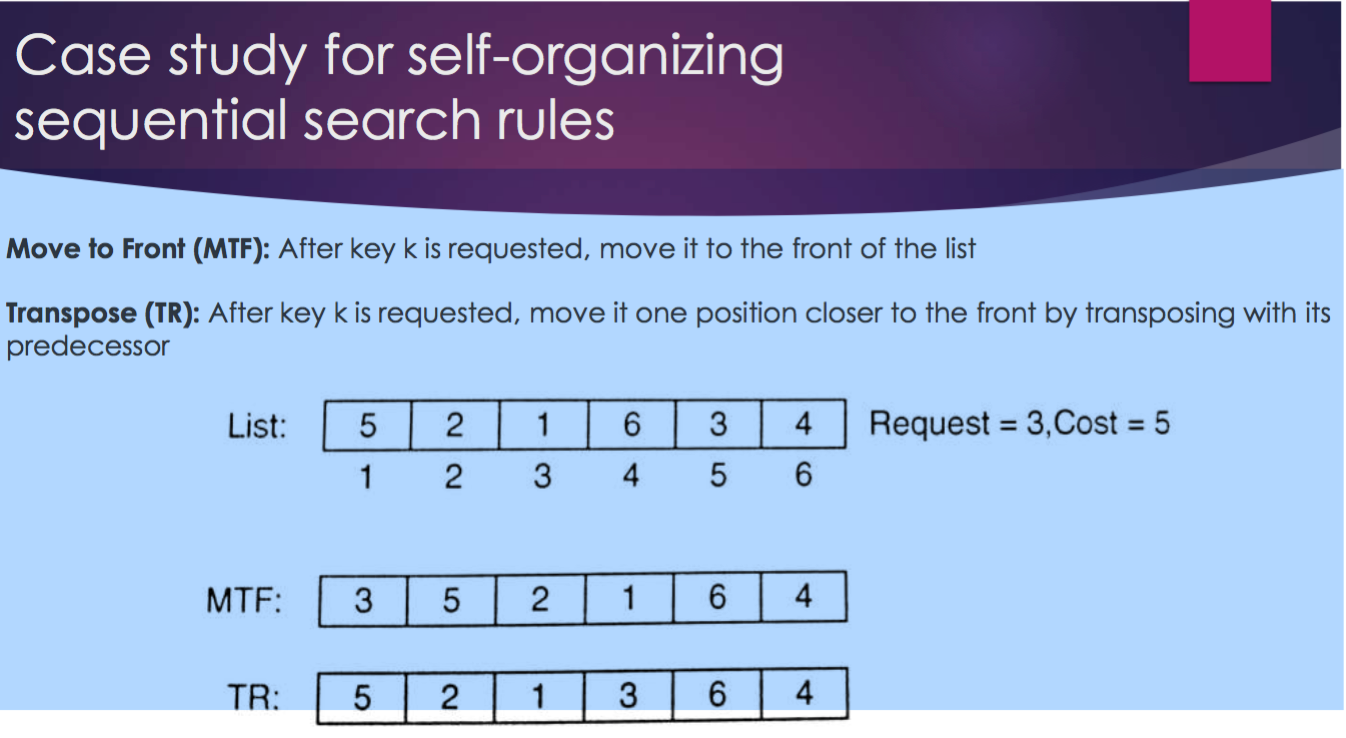

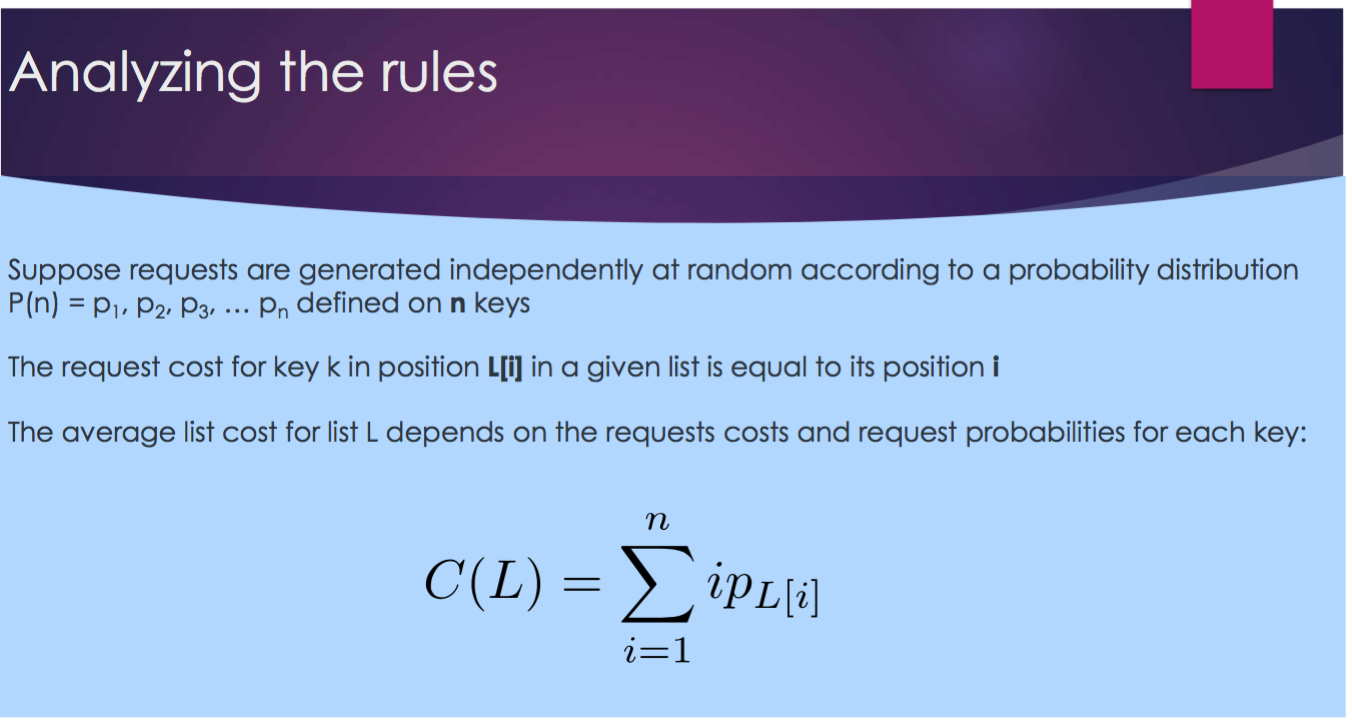 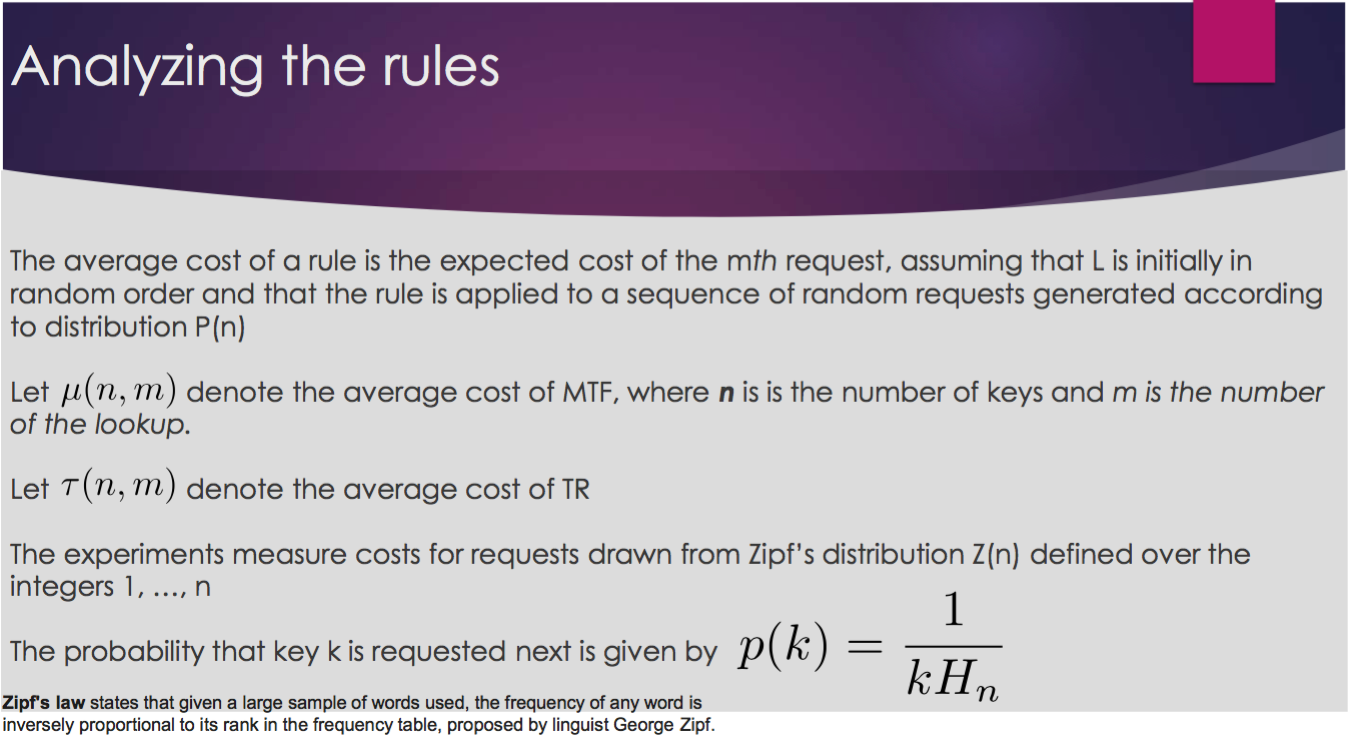

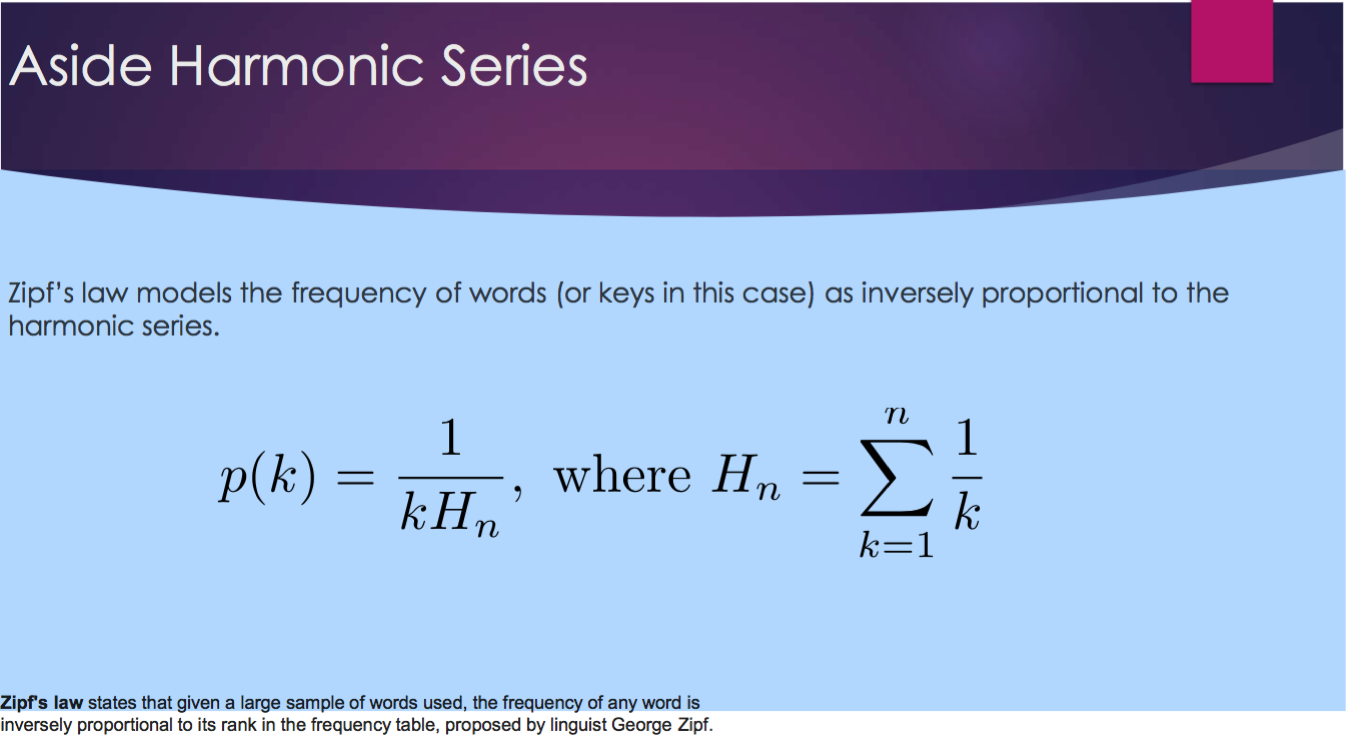 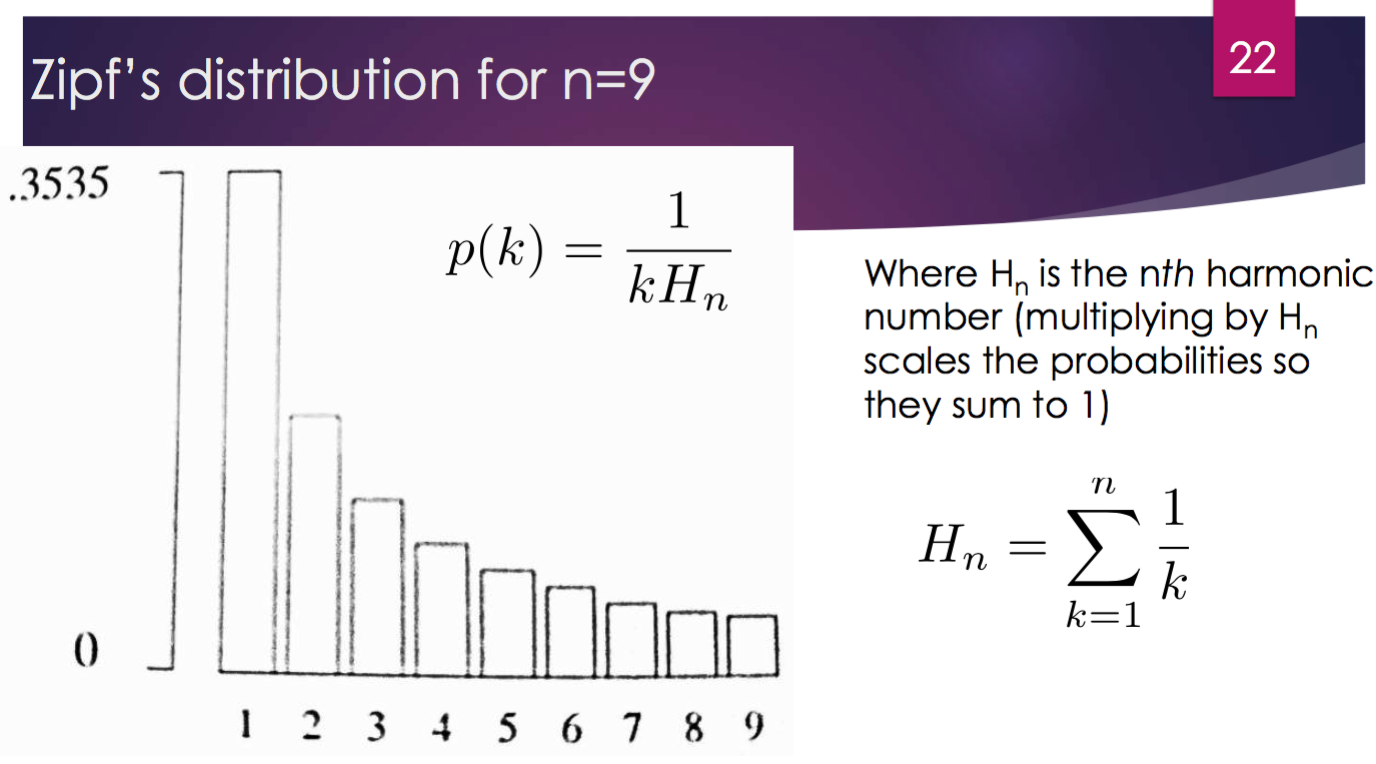 

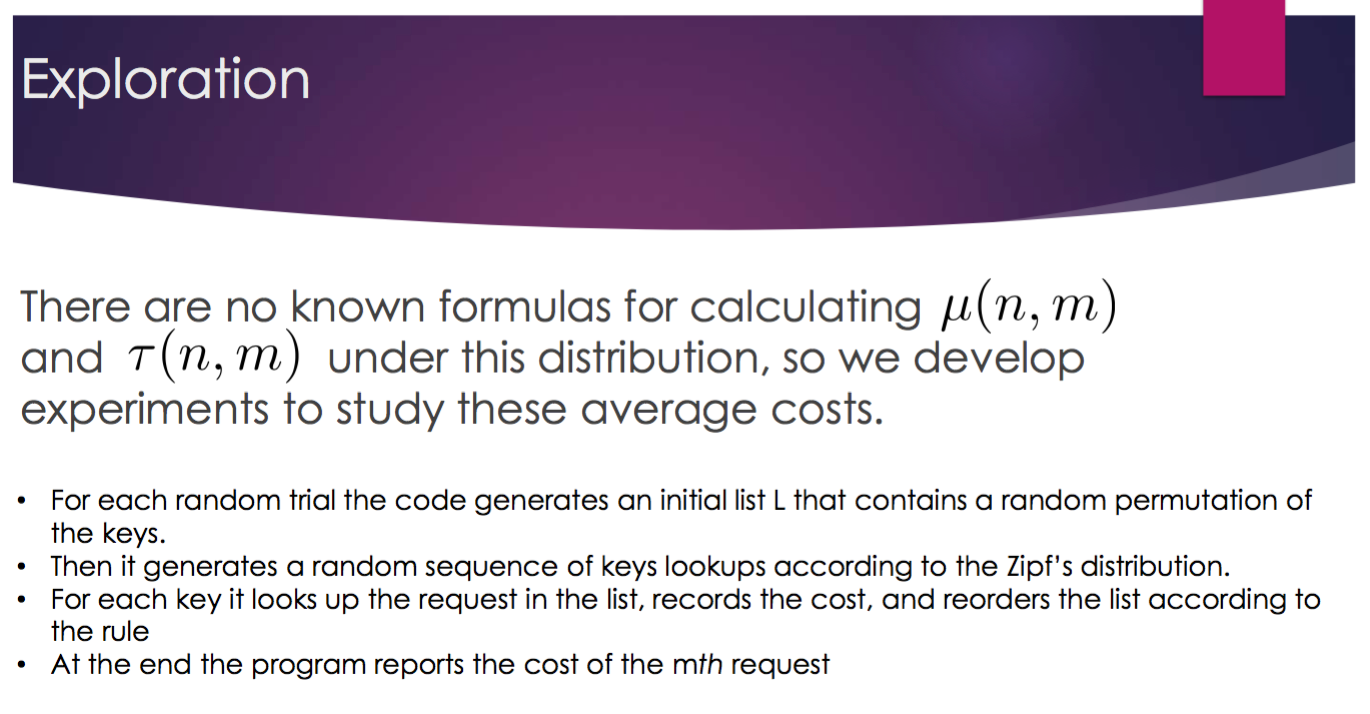 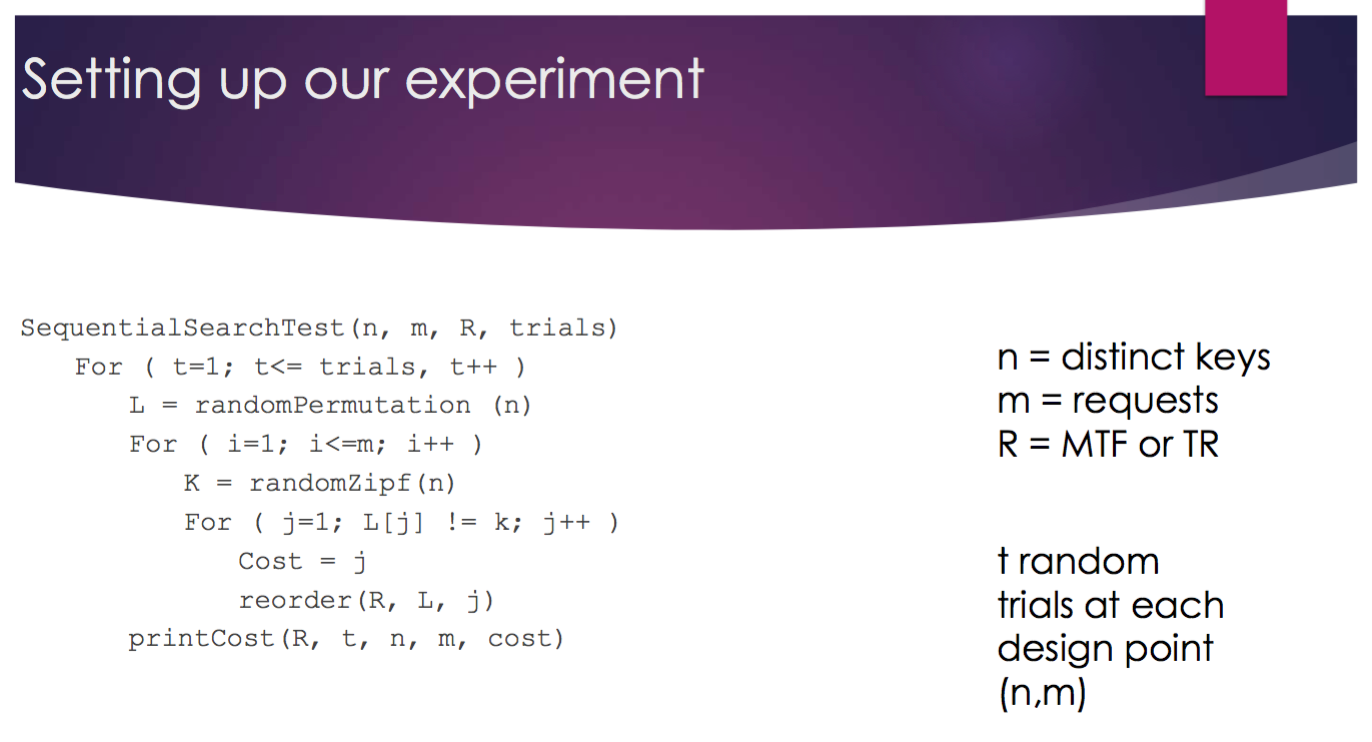  

## 1. The Zipf Distribution

We begin by establishing a method for sampling from a Zipfian distribution. This is not a critical piece of this case study but provides one possible model for the distribution of requests arriving for key searches in the list of keys, and it's interesting to learn more about the Zipf distribution and a bit of its history (see, for example, the nice *Wikipedia* entry at https://en.wikipedia.org/wiki/Zipf%27s_law).

The definition of the zipf(*j*, *n*) probability density function (pdf) appears at the end of this mlx file, and in the code shown immediately below this text we illustrate the resulting pdf for a specific **numberOfKeys**. Along the way, we verify that for any specific number of keys, the sum of the resulting collection of probabilities is 1, as required in any well-behaved pdf. In the *next* section below we actually implement a process for randomly sampling from a Zipf distribution.

% set a convenient format for printing values
format shortG

% set the number of "keys" considered in each list of keys
% the so-called keys will be integers 1-numberOfKeys
numberOfKeys = 10;

% allocate space for storing the relative probabilities of the keys
zipfValues = zeros(numberOfKeys, 1);

% establish the probability for each key value,
% using the zipf() function defined in the functions section
% at the bottom of this mlx file
for i = 1:1:numberOfKeys
  zipfValues(i) = zipf(i, numberOfKeys);
end

% check our calculations: the sum of the calculated zipf values
% should be (approximately) 1
sum(zipfValues)

ans =             1


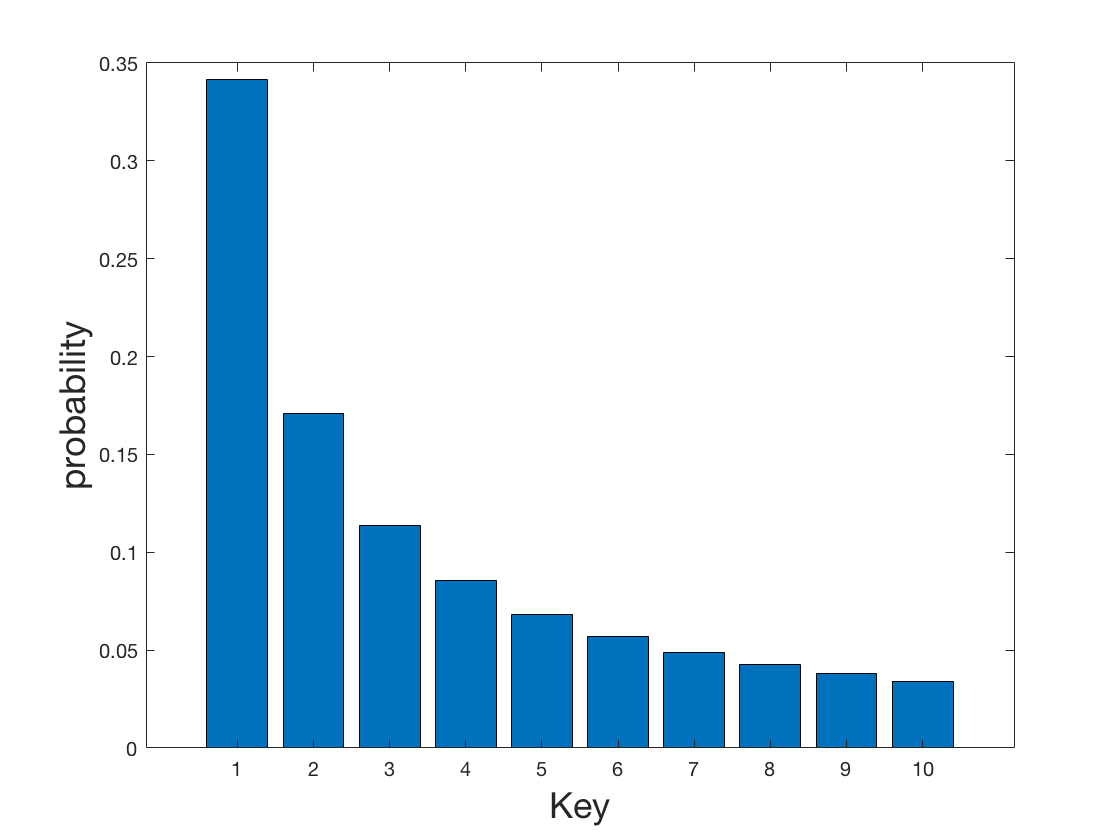

% look at the resulting probability density function (pdf)
bar(zipfValues)
xlabel('Key', 'FontSize', 18)
ylabel('probability', 'FontSize', 18)

## 2. Sampling from a Zipf Distribution

In this section we generate pseudo-random integers sampled from a Zipf distribution of integers, using a rejection method (as discussed in Kalos & Whitlock (2008), Section 3.5, pp 53–61).

Notice that the pdf has a maximum value that depends on the number of keys *n*. When *n* = 10, for example, the max probability (associated with the key 1) is:

double(zipf(1, 10))

ans =       0.34142


We effect a sampling of the Zipf distribution by first picking an integer x randomly from 1 to numberOfKeys, then a second random number y = maxProb * rand(0,1). If y ≤ zipfValues(x), we keep x as one of our randomly-generated values, else we discard it and repeat the process.

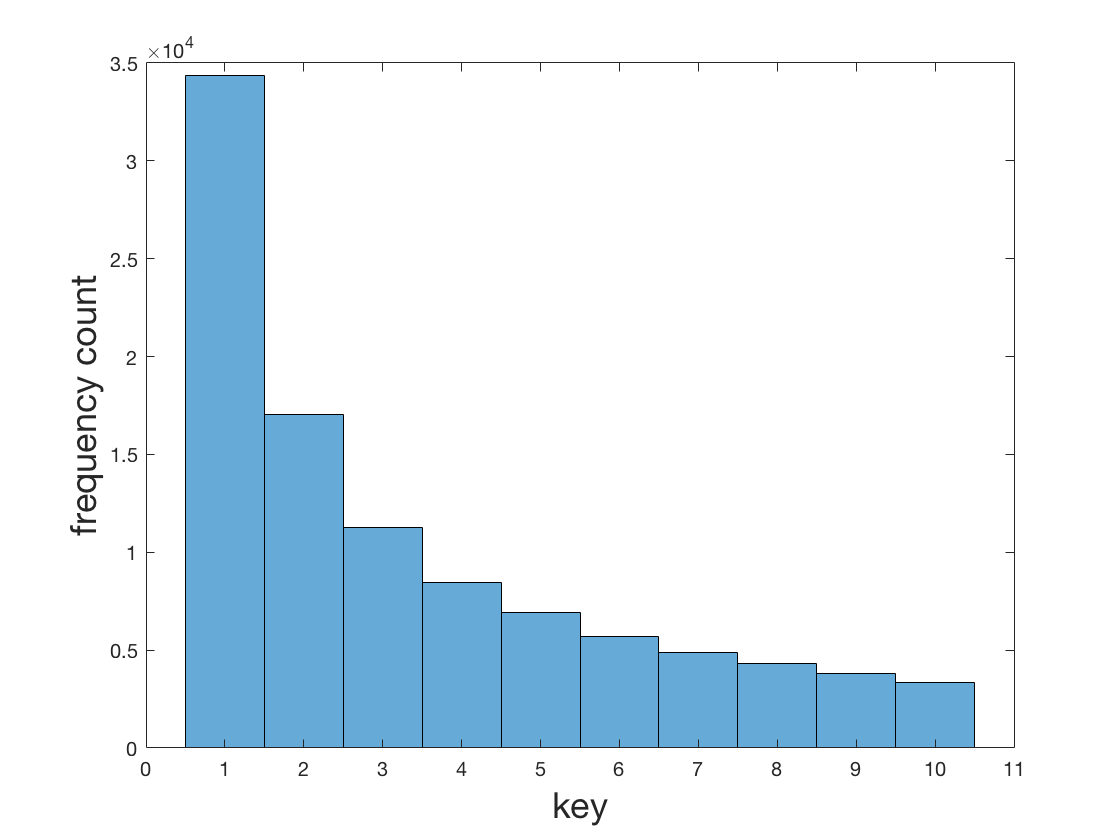

% establish the maximum of the pdf function for our context
maxProb = double(zipf(1, numberOfKeys));

% set the desired sample size
desiredNumberOfValues = 100000;

% set the number of values in sample so far:
actualNumberOfValues = 0;

% allocate space for the eventual sample:
sampleOfValues = zeros(desiredNumberOfValues, 1);

% perform the rejection-based sampling
while actualNumberOfValues < desiredNumberOfValues
  % pick a random key
  rand01 = randi(numberOfKeys);
  % pick a random real from (0, maxProb)
  rand02 = maxProb * rand();
  % determine if initial rand01 should be kept or rejected
  if rand02 <= zipfValues(rand01)
    actualNumberOfValues = actualNumberOfValues + 1;
    sampleOfValues(actualNumberOfValues) = rand01;
  end
end

% take a look at the (frequency) distribution created
histogram(sampleOfValues)
xlabel('key', 'FontSize', 18)
ylabel('frequency count', 'FontSize', 18)

% express the distribution in terms of probabilities:
sampleOfValuesProbabilities = zeros(numberOfKeys, 1);
for i = 1:numberOfKeys
  sampleOfValuesProbabilities(i) = sum(sampleOfValues(:)==i);
end
sampleOfValuesProbabilities = ...
  sampleOfValuesProbabilities/sum(sampleOfValuesProbabilities)

sampleOfValuesProbabilities =       0.34347
      0.17024
      0.11255
      0.08437
      0.06938
      0.05673
      0.04856
      0.04309
      0.03824
      0.03337


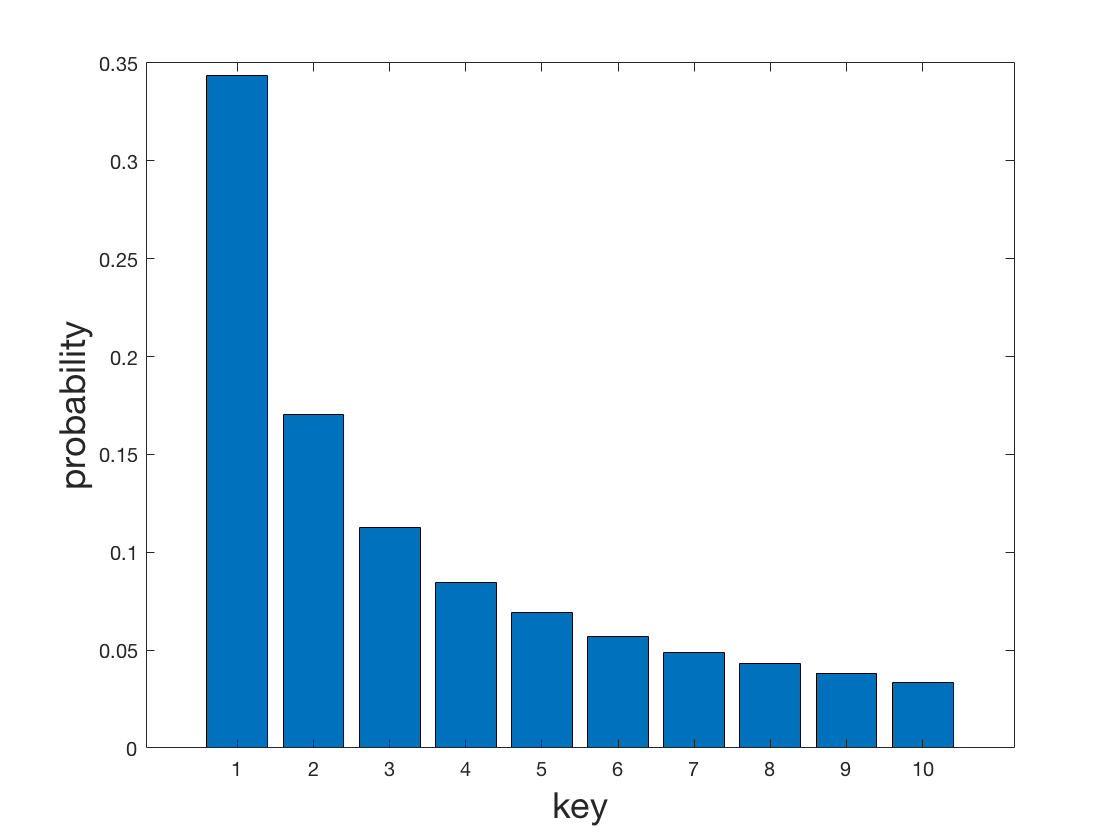

% take a look at the probability distribution created
bar(sampleOfValuesProbabilities)
xlabel('key', 'FontSize', 18)
ylabel('probability', 'FontSize', 18)

And we can take a quick look at the difference between the empirically-generated probabilities and the theoretical ones, standardized over the theoretical probabilities. The for large samples (say ≥ 100,000), the differences tend to have a max absolute value less than about 5% over time, and generally much smaller differences:

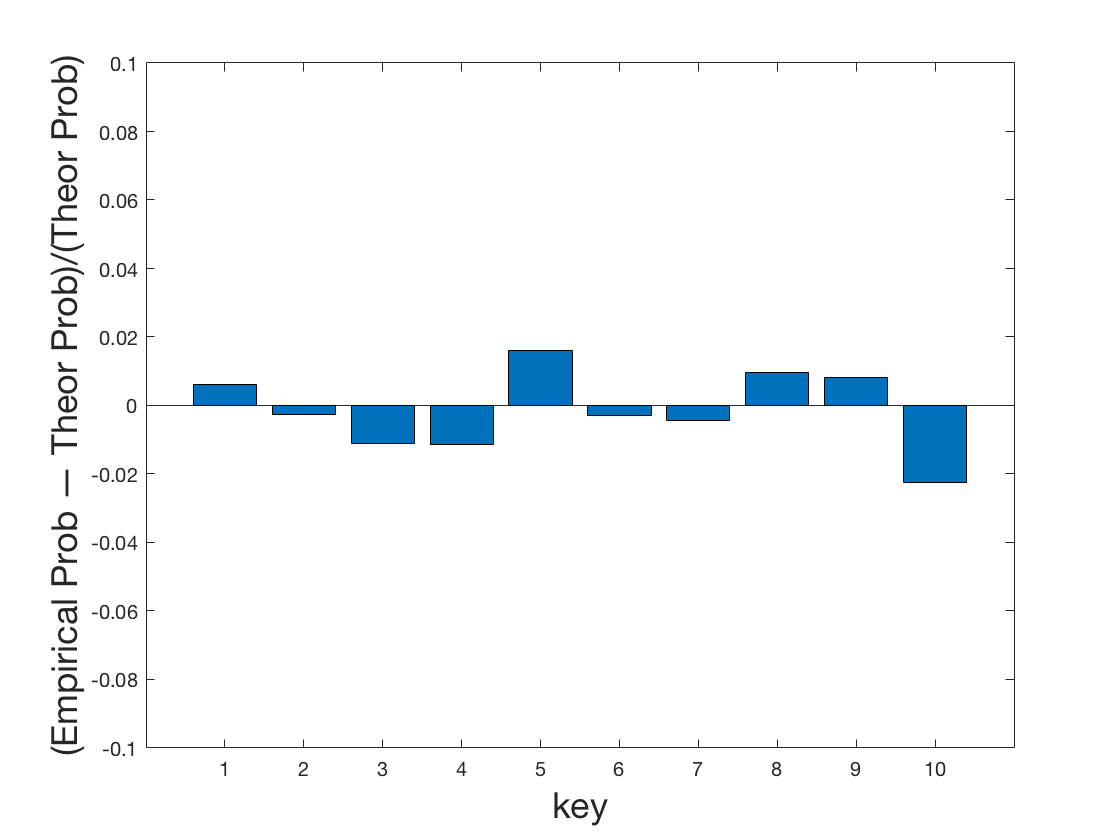

% look at the difference between the empirical distribution values
% and the theoretical Zipf distribution values, std'ized by the theoretical values:
xs = 1:1:10;
stdDeltas = (sampleOfValuesProbabilities-zipfValues)./zipfValues;
bar(xs, stdDeltas);
xlabel('key', 'FontSize', 18)
ylabel('(Empirical Prob — Theor Prob)/(Theor Prob)', 'FontSize', 18)
axis([0 11 -0.1 0.1])

## 3. Initial Randomly-Ordered List of Keys & Accessing Those Keys

MATLAB has some convenient tools for this project, including **randperm()** for establishing the initial randomly-ordered list or array of keys and **find()** for determining the location of an element in our list or array.

numberOfKeys = 10;
requestedKey = randi(numberOfKeys)

requestedKey =      2


% create a random permutation of the numberOfKeys keys:
arrayOfKeys = randperm(numberOfKeys)

arrayOfKeys =      4     1     8     7     9     5     6     3     2    10


% determine the location (and thus the “cost”) of a specific key:
find(arrayOfKeys==requestedKey)

ans =      9


## 4. Basic Approaches for Implementing the Move-to-Front (MTF) and Transpose (TR) Operations

MATLAB doesn't have a built-in function for either the Move-to-Front (MTF) or Transpose (TR) operations, so we need to implement these operations on our own in some simple way.

% consider a number of keys 1–n, a requested key, and an initial random
% array of the numberOfKeys keys
numberOfKeys = 10;
requestedKey = randi(numberOfKeys)

requestedKey =     10


% create a random permutation of the numberOfKeys keys:
arrayOfKeys = randperm(numberOfKeys)

arrayOfKeys =      8     6     3    10     9     5     2     7     4     1


% determine the location (and thus the “cost”) of a specific key,
% in two different ways, one using find() and the other using a logical
% array
indexFound = find(arrayOfKeys==requestedKey)

indexFound =      4


tempLogicalArray = arrayOfKeys == requestedKey

tempLogicalArray = 1×10 logical array
   0   0   0   1   0   0   0   0   0   0


### Move-to-Front (MTF)

The Move-to-Front operation, using logical indexing:

% Move-to-Front by constructing a new array from the old using logical indexing
% If indexFound == 1, no need to rearrange anything, but the logical
% indexing will take care of it for us.
arrayOfKeysMTF = [arrayOfKeys(tempLogicalArray) arrayOfKeys(~tempLogicalArray)]

arrayOfKeysMTF =     10     8     6     3     9     5     2     7     4     1


### Swap-with-Neighbor (SWN) (Called Transpose (TR) in the Original Treament)

The Swap-with-Neighbor (SWN) operation (originally referred to as the Transpose (TR) operation, but “transpose” means several different things), using matrix multiplication with a suitably modified version of the identity matrix:

% Transpose (TR) using the find() approach along with matrix multiplication --
% no obvious easy way to use the logical indexing for this one.
% Again, if indexFound == 1, no need to rearrange anything.
% Below we use a numberOfKeys x numberOfKeys identity matrix I
% then swap the indexFound row with the indexFound-1 row
% then use that to transform the original arrayOfKeys to the new one
if indexFound ~= 1
  % establish the numberOfKeys X numberOfKeys identity matrix
  multiplierMatrix = eye(numberOfKeys);
  % swap the necessary rows
  multiplierMatrix([indexFound-1 indexFound],:) = multiplierMatrix([indexFound indexFound-1],:);
  % generate the new arrayOfKeys using matrix multiplication
  arrayOfKeysSWN = (multiplierMatrix * arrayOfKeys')';
else
  % key was already first in array, so leave it alone
  arrayOfKeysSWN = arrayOfKeys;
end
arrayOfKeysSWN

arrayOfKeysSWN =      8     6    10     3     9     5     2     7     4     1


Of course, a much more straightforward transpose method can simply use a traditional 3-step copy/paste procedure, simplified a bit because we already have the variable **requestedKey** holding the sought-after key, like this:

if indexFound ~= 1
    arrayOfKeysSWNAlt01 = arrayOfKeys;
    arrayOfKeysSWNAlt01(indexFound) = arrayOfKeysSWNAlt01(indexFound-1);
    arrayOfKeysSWNAlt01(indexFound-1) = requestedKey;
else
    % key was already first in array, so leave it alone
    arrayOfKeysSWNAlt01 = arrayOfKeys;
end
arrayOfKeysSWNAlt01

arrayOfKeysSWNAlt01 =      8     6    10     3     9     5     2     7     4     1


And combining the two transpose approach ideas, we have the even simpler approach:

if indexFound ~= 1
    arrayOfKeysSWNAlt02 = arrayOfKeys;
    arrayOfKeysSWNAlt02([indexFound-1 indexFound]) = arrayOfKeysSWNAlt02([indexFound indexFound-1]);
else
    % key was already first in array, so leave it alone
    arrayOfKeysSWNAlt02 = arrayOfKeys;
end
arrayOfKeysSWNAlt02

arrayOfKeysSWNAlt02 =      8     6    10     3     9     5     2     7     4     1


At the end of this LiveScript notebook, we encapsulate these ideas into 2 different functions:

moveToFront(arrayOfKeys, index *n*) —> moves the element in arrayOfKeys at index *n* to index 1 (assumes 1 ≤ *n* < length(arrayOfKeys));

swapFrontward(arrayOfKeys, index *n*) —> swaps elements in arrayOfKeys at indices *n* and *n*–1 (assumes 1 ≤ *n* < length(arrayOfKeys)).

We will build into the swapFrontward function the check to see if the element is already at the front — that will then make the two different functions more consistently alike, since the moveToFront function will handle such a condition automatically, and allow more modular “plug-in” operation of the two functions in an interchangeable way.

See the APPENDIX below for the formal definitions.

To test the formal functions, we organize the inputs and outputs below:

% Testing the moveToFront() fxn
fprintf(strcat('arrayOfKeys = [', repmat('%d ', 1, length(arrayOfKeys)), ']\n',...
    'indexFound = %d\n', ...
    'key = %d\n', ...
    'new array:\n', ...
    'arrayOfKeys = [', repmat('%d ', 1, length(arrayOfKeys)), ']' ), ...
    arrayOfKeys, indexFound, arrayOfKeys(indexFound), moveToFront(arrayOfKeys, indexFound))

arrayOfKeys = [8 6 3 10 9 5 2 7 4 1]
indexFound = 4
key = 10
new array:
arrayOfKeys = [10 8 6 3 9 5 2 7 4 1]

% Testing the swapFrontward() fxn
fprintf(strcat('arrayOfKeys = [', repmat('%d ', 1, length(arrayOfKeys)), ']\n',...
    'indexFound = %d\n', ...
    'key = %d\n', ...
    'new array:\n', ...
    'arrayOfKeys = [', repmat('%d ', 1, length(arrayOfKeys)), ']' ), ...
    arrayOfKeys, indexFound, arrayOfKeys(indexFound), swapFrontward(arrayOfKeys, indexFound))

arrayOfKeys = [8 6 3 10 9 5 2 7 4 1]
indexFound = 4
key = 10
new array:
arrayOfKeys = [8 6 10 3 9 5 2 7 4 1]

## APPENDIX: Function Definitions

### The zipf(*j*, *n*) function

The zipf(j, n) function below returns the Zipfian distribution-based probability of the jth-ranked item of a collection of *n* possible items:

function p = zipf(j, n)
% Returns p(j) = 1/(j H_n), where H_n = sum(1/k) for k = 1 to n,
% a standardized pdf version of Zipf's Law.
% Zipf's Law states that "given some corpus of natural language utterances,
% the frequency of any word is inversely proportional to its rank in the
% frequency table" [https://en.wikipedia.org/wiki/Zipf%27s_law.
syms k;
p = 1/(j * symsum(1/k, k, [1 n]));
end

### moveToFront() function

function returnArray = moveToFront(inputArray, n)
% Returns the 1-D inputArray with the nth item moved to index 1.
% inputArray :  a non-empty 1D array;
% n          :  a positive integer such that 1 ≤ n ≤ length(inputArray)
% returnArray:  the inputArray but with the nth item now appearing at
%               index 1 and items originally at indices 1, 2, …, (n-1) shifted
%               rightward to indices 2, 3, …, n
tempLogicalArray = inputArray == inputArray(n);
returnArray = [inputArray(tempLogicalArray) inputArray(~tempLogicalArray)];
end

### swapFrontward() function

function returnArray = swapFrontward(inputArray, n)
% Returns the 1-D inputArray with items at index n and (n-1) swapped.
% inputArray :  a non-empty 1D array;
% n          :  a positive integer such that 1 ≤ n ≤ length(inputArray)
% returnArray:  the inputArray but with the nth and (n-1)th items swapped;
%               if n = 1, returnArray = inputArray
returnArray = inputArray;
if n ~= 1
    returnArray([n-1 n]) = returnArray([n n-1]);
    % if n == 1, no swapping needed because item is
    % already at front of array
end
end